clear
rng(203829)
addpath('functions')

plotPos = [100 100 800, 400];

Ts = 10;

% System matrices
A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];

B = [1.4459,  0.0622;
     0.0622,  1.4459;
    13.3615,  0.0077;
     0.0077, 13.3615];

C = [1, 0, 0, 0;
     0, 1, 0, 0];

D = [];

% Weighting matrices
R1 = [8.0209, 0.2260, 1.5334, 0.0812;
      0.2260, 8.0209, 0.0812, 1.5334;
      1.5334, 0.0812, 7.4082, 0.0172;
      0.0812, 1.5334, 0.0172, 7.4082];

R2 = eye(2);  % identity matrix of size equal to # of inputs


sys = ss(A,B,C,D,Ts);



lambda = eig(A)

lambda =     0.5841
    0.5891
    0.9044
    0.9498



K = place(A,B,lambda/2)

K =     0.0742    0.0043    0.0477    0.0011
    0.0048    0.0792    0.0012    0.0490



sys_2 = ss((A - B*K),B,C,D,Ts);

sys_c = ss((A - B*K),B/dcgain(sys_2),C,D,Ts);

step(sys_c)

dlqe(A,eye(4),C,R1,R2)

ans =     0.9003    0.0030
    0.0030    0.9003
    0.3442    0.0070
    0.0070    0.3442


%% --- system definition ---
Ts = 10;    % sample time [s]

A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];

B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];

C = [1, 0, 0, 0;
     0, 1, 0, 0];

% cost / noise‐covariance matrices (as given)
Q_c = [8.0209, 0.2260, 1.5334, 0.0812;
       0.2260, 8.0209, 0.0812, 1.5334;
       1.5334, 0.0812, 7.4082, 0.0172;
       0.0812, 1.5334, 0.0172, 7.4082];
R_c = eye(2);    % = R2

W = Q_c;         % assumed process‐noise covariance
V = R_c;         % assumed measurement‐noise covariance

%% --- LQR controller design ---
% [K, ~, ~] = dlqr(A, B, eye(4), eye(2));
lambda = eig(A)

lambda =     0.5841
    0.5891
    0.9044
    0.9498


K = place(A,B,lambda*0.85)

K =     0.0086    0.0019    0.0146    0.0009
    0.0022    0.0126    0.0009    0.0170



%% --- Kalman filter design (steady‐state) ---
%   L is the state‐estimator gain:  xhat+ = A*xhat + B*u + L*(y - C*xhat)
[L, P, E] = lqe(A, eye(4), C, W, V);

%% --- simulation setup ---
Tfinal = 1000;            % total simulation time [s]
N = Tfinal / Ts;         % number of steps
x     = zeros(4, N+1);   % true state
xhat  = zeros(4, N+1);   % estimated state
y     = zeros(2, N);     % measurements
yhat  = zeros(2, N);     % predicted outputs
u     = zeros(2, N);     % control inputs

rng(0);  % for reproducible noise

T = N; % Periode in sampels
ref1 = 10*square(2*pi*1/T*(1:Tfinal),50);
ref2 = zeros(1,Tfinal);
ref = [ref1;ref2];
dcG = (C*(eye(4) - (A-B*K))^(-1) * B)^-1

dcG =     0.0373   -0.0037
   -0.0037    0.0440


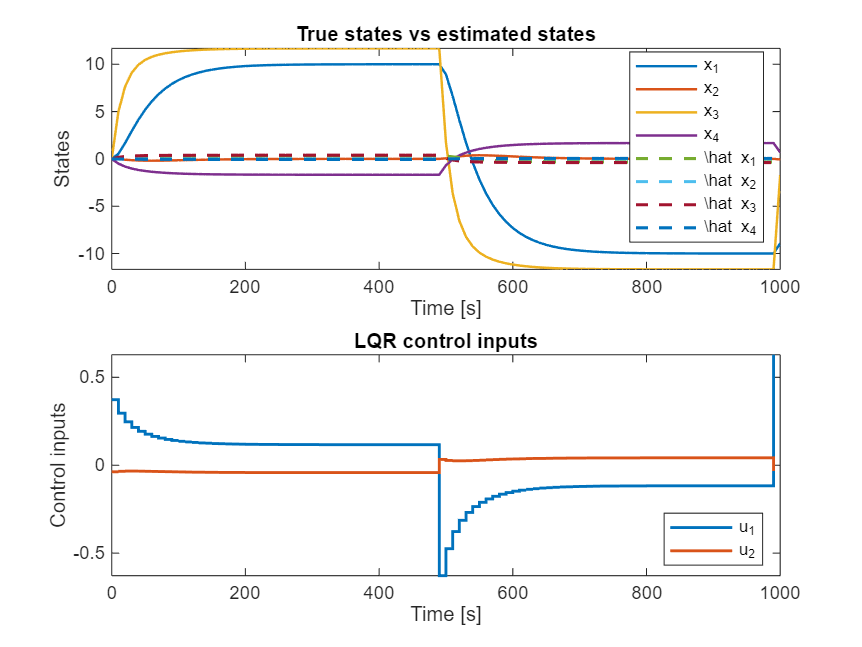


for k = 1:N
    %--- measurement (with noise) ---
    v = mvnrnd(zeros(2,1), V)';     % measurement noise 
    v = 0;
    y(:,k) = C*x(:,k) + v;
    
    %--- control law (uses estimated state) ---
    u(:,k) = -K * x(:,k) + dcG*ref(:,k);
    
    %--- true‐state update (with process noise) ---
    w = mvnrnd(zeros(4,1), W)';     % process noise
    w = 0;
    x(:,k+1) = A*x(:,k) + B*u(:,k) + w;
    
    %--- estimator update ---
    xhat(:,k+1) = A*xhat(:,k) + B*u(:,k) + L*(y(:,k) - C*xhat(:,k));
    yhat(:,k)   = C*xhat(:,k);
end

time = 0:Ts:Tfinal;

%% --- plotting ---
figure;
subplot(2,1,1);
plot(time, x, '-','LineWidth',1.2); hold on
plot(time, xhat./30, '--','LineWidth',1.5);
xlabel('Time [s]'); ylabel('States');
legend({'x_1','x_2','x_3','x_4',...
        '\\hat x_1','\\hat x_2','\\hat x_3','\\hat x_4'},...
        'Location','best');
title('True states vs estimated states');

subplot(2,1,2);
stairs(time(1:end-1), u','LineWidth',1.4);
xlabel('Time [s]'); ylabel('Control inputs');
legend('u_1','u_2','Location','best');
title('LQR control inputs');

%% --- system definition and LQR design (unchanged) ---
Ts = 10;                          % sample time [s]
A = [0.7901, 0.0238, 0.1667, 0.0081;
     0.0238, 0.7901, 0.0081, 0.1667;
     0.1667, 0.0081, 0.7236, 0.0014;
     0.0081, 0.1667, 0.0014, 0.7236];
B = [ 1.4459,  0.0622;
      0.0622,  1.4459;
     13.3615,  0.0077;
      0.0077, 13.3615];
C = [1, 0, 0, 0;
     0, 1, 0, 0];

Q_c = [8.0209, 0.2260, 1.5334, 0.0812;
       0.2260, 8.0209, 0.0812, 1.5334;
       1.5334, 0.0812, 7.4082, 0.0172;
       0.0812, 1.5334, 0.0172, 7.4082];
R_c = eye(2);

[K,~,~] = dlqr(A,B,diag([1,1,0,0]),R_c*1000);
% lambda = eig(A)
% K = place(A,B,lambda*0.85)

%% --- reference and DC-gain computation ---
Tfinal = 1000;                % total sim time [s]
N      = Tfinal / Ts;        % # of steps
T      =  N;                  % choose one period = N steps

% 50%-duty, ±10 square wave in the first output channel:
ref1 = 50 * square(2*pi*(1/T)*(1:N), 50);
ref2 = zeros(1, N);
ref  = [ref1; ref2];         % 2×N reference

% compute DC-gain inverse for perfect steady-state tracking:
dcG = (C*(eye(4) - (A-B*K))^(-1) * B)^-1

dcG =     0.0320   -0.0017
   -0.0017    0.0320


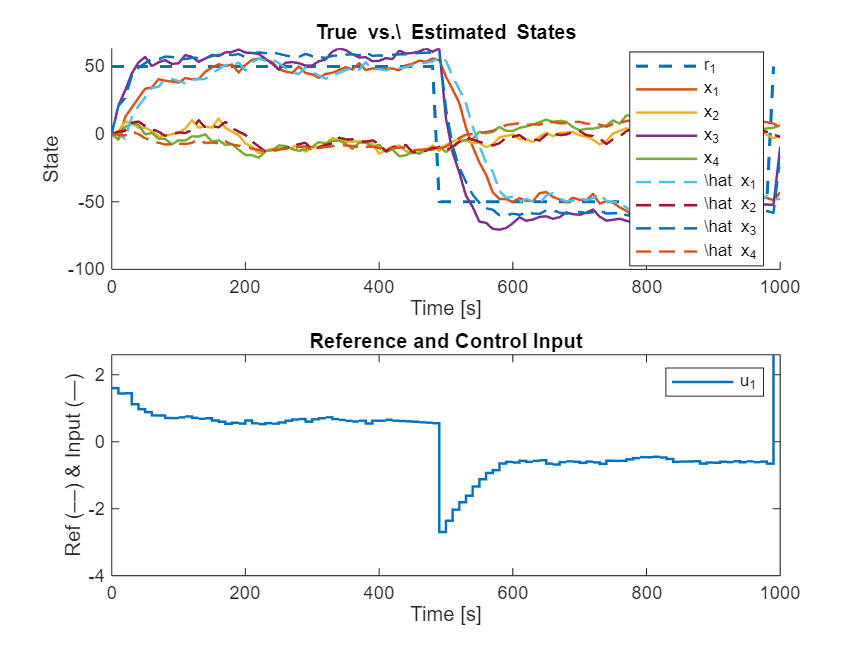


%% --- Kalman and simulation setup ---
W    = Q_c;               % process‐noise cov
V    = R_c;               % measurement‐noise cov
x    = zeros(4, N+1);     % true state
xhat = zeros(4, N+1);     % estimated state
P    = 100*eye(4);        % init error‐covariance
u    = zeros(2, N);
y    = zeros(2, N);

rng(0);
for k = 1:N
  %--- measurement ---
  y(:,k) = C*x(:,k) + mvnrnd(zeros(2,1),V)';

  %--- control law w/ feed-forward ---
  u(:,k) = -K*xhat(:,k) + dcG * ref(:,k);

  %--- true‐state update ---
  x(:,k+1) = A*x(:,k) + B*u(:,k) + mvnrnd(zeros(4,1),W)';

  %--- Kalman predict ---
  xhat_pred = A*xhat(:,k) + B*u(:,k);
  P_pred    = A*P*A' + W;

  %--- Kalman update ---
  S      = C*P_pred*C' + V;
  Kf     = P_pred*C'/S;
  innov  = y(:,k) - C*xhat_pred;
  xhat(:,k+1) = xhat_pred + Kf*innov;
  P      = (eye(4) - Kf*C)*P_pred;
end

%% --- plotting ---
time = 0:Ts:Tfinal;
figure;
subplot(2,1,1);
hold on
plot(time(1:end-1), ref(1,:), '--','LineWidth',1.5);
plot(time, x, '-', time, xhat, '--','LineWidth',1.2);hold off
xlabel('Time [s]'); ylabel('State');
legend({'r_1','x_1','x_2','x_3','x_4','\\hat x_1','\\hat x_2','\\hat x_3','\\hat x_4'},...
       'Location','best');
title('True vs.\\ Estimated States');

subplot(2,1,2); 
stairs(time(1:end-1), u(1,:), '-','LineWidth',1.2);
xlabel('Time [s]'); ylabel('Ref (––) & Input (—)');
legend('u_1');
title('Reference and Control Input');